A = [0 20; 1 0 ]

A =      0    20
     1     0


B = [0; 1]

B =      0
     1


C = [0 1]

C =      0     1



transpose(A)

ans =      0     1
    20     0


transpose(B)

ans =      0     1


transpose(C)

ans =      0
     1




transpose(A)*transpose(C)

ans =      1
     0



rank(transpose(B))

ans = 1

rank([transpose(C) transpose(A)*transpose(C)])

ans = 2

c_ctrl_t = [transpose(C) transpose(A)*transpose(C)]

c_ctrl_t =      0     1
     1     0


inv(c_ctrl_t)

ans =      0     1
     1     0



syms lambda

expand((lambda+10)^2)

$$ans = \lambda^{2}+20\,\lambda +100$$


at = transpose(A);
delta_at = at^2 + 20*at + 100*eye(2)

delta_at =    120    20
   400   120



K_e = transpose([0 1]*inv(c_ctrl_t)* delta_at)

K_e =    120
    20



c_ctrl = [B A*B]

c_ctrl =      0    20
     1     0


inv(c_ctrl)

ans =          0    1.0000
    0.0500         0


rank(c_ctrl)

ans = 2


expand((lambda+2-5i)*(lambda+2+5i))

$$ans = \lambda^{2}+4\,\lambda +29$$

delta_a = A^2 + 4*A + 29*eye(2)

delta_a =     49    80
     4    49



K = [0 1] * inv(c_ctrl)*delta_a

K =     2.4500    4.0000




ss(A, B, C, 0)

ans =
 
  A = 
       x1  x2
   x1   0  20
   x2   1   0
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
       x1  x2
   y1   0   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



time = 0:0.01:3;

% 1
r_func = @(t,r, u) [A zeros(2); K_e*C A-(K_e*C)]*r+[B; B]*u

r_func = function_handle with value:
    @(t,r,u)[A,zeros(2);K_e*C,A-(K_e*C)]*r+[B;B]*u


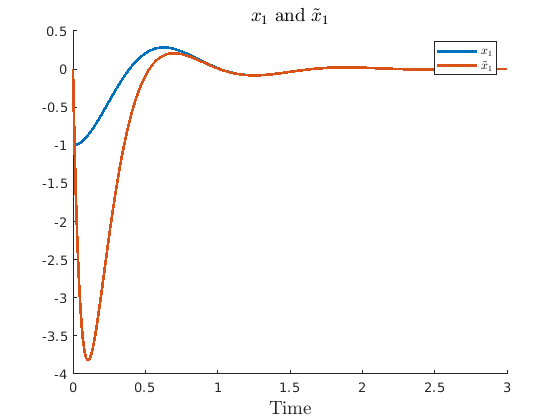

[t, r_10] = ode45(@(t, r) r_func(t, r, -K*r(1:2)), time, [-1; 0; 0; 1;]);

figure
title("$x_1$ and $\tilde{x}_1$", 'Interpreter', 'latex', "FontSize", 14);
xlabel("Time", 'Interpreter', 'latex', "FontSize", 14);
hold on

plot(time, r_10(:,1), 'LineWidth', 2)
plot(time, r_10(:,3), 'LineWidth', 2)

legend(["$x_1$", "$\tilde{x}_1$"], 'Interpreter', "latex")

hold off
exportgraphics(gcf,'figures/c1-x1-plot.png','Resolution',300)

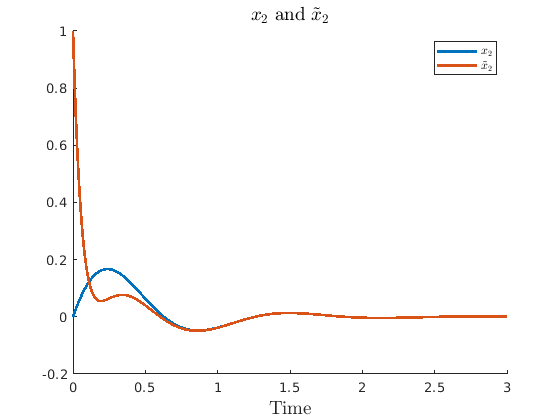


figure
title("$x_2$ and $\tilde{x}_2$", 'Interpreter', 'latex', "FontSize", 14);
xlabel("Time", 'Interpreter', 'latex', "FontSize", 14);
hold on

plot(time, r_10(:,2), 'LineWidth', 2)
plot(time, r_10(:,4), 'LineWidth', 2)

legend(["$x_2$", "$\tilde{x}_2$"], 'Interpreter', "latex")

hold off
exportgraphics(gcf,'figures/c1-x2-plot.png','Resolution',300)

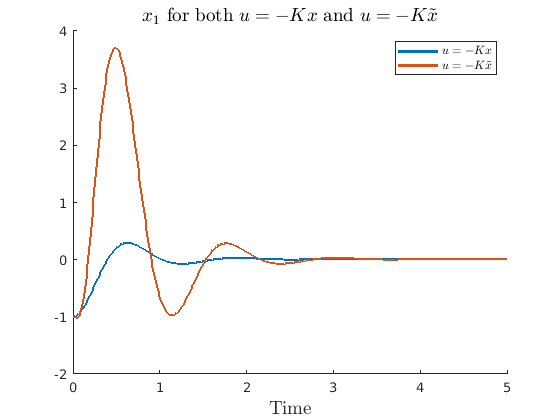

% Part C 2
time = 0:0.01:5;
[t, r_e10] = ode45(@(t, r) r_func(t, r, -K*r(3:4)), time, [-1; 0; 0; 1;]);
[t, r_10] = ode45(@(t, r) r_func(t, r, -K*r(1:2)), time, [-1; 0; 0; 1;]);

figure
title("$x_1$ for both $u=-Kx$ and $u=-K\tilde{x}$", 'Interpreter', 'latex', "FontSize", 14);
xlabel("Time", 'Interpreter', 'latex', "FontSize", 14);
hold on

plot(time, r_10(:,1), 'Linewidth', 2)
% plot(time, r_10(:,1), 'Linewidth', 2)
plot(time, r_e10(:,1), 'LineWidth', 2)

legend(["$u=-Kx$", "$u=-K\tilde{x}$"], 'Interpreter', "latex")

hold off
exportgraphics(gcf,'figures/c2-x1-plot.png','Resolution',300)

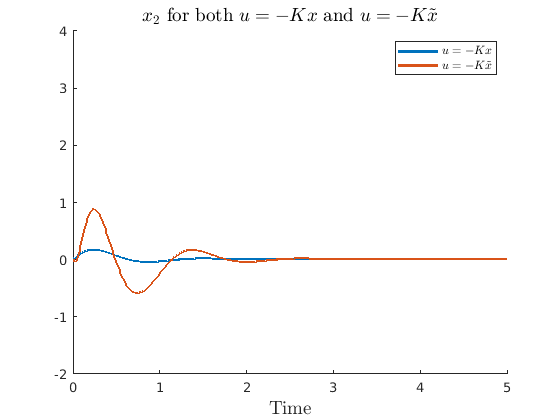


figure
title("$x_2$ for both $u=-Kx$ and $u=-K\tilde{x}$", 'Interpreter', 'latex', "FontSize", 14);
xlabel("Time", 'Interpreter', 'latex', "FontSize", 14);
hold on

plot(time, r_10(:,2), 'LineWidth', 2)
plot(time, r_e10(:,2), 'LineWidth', 2)
ylim([-2,4])

legend(["$u=-Kx$", "$u=-K\tilde{x}$"], 'Interpreter', "latex")

hold off
exportgraphics(gcf,'figures/c2-x2-plot.png','Resolution',300)

% Part C 3

% -1
time = 0:0.01:5;
expand((lambda+1)^2)

$$ans = \lambda^{2}+2\,\lambda +1$$

delta_at = at^2 +2*at + 1*eye(2)

delta_at =     21     2
    40    21



K_e_1 = transpose([0 1]*inv(c_ctrl_t)* delta_at)

K_e_1 =     21
     2



r_func = @(t,r, u) [A zeros(2); K_e_1*C A-(K_e_1*C)]*r+[B; B]*u

r_func = function_handle with value:
    @(t,r,u)[A,zeros(2);K_e_1*C,A-(K_e_1*C)]*r+[B;B]*u


[t, r_1] = ode45(@(t, r) r_func(t, r, -K*r(1:2)), time, [-1; 0; 0; 1;]);
[t, r_e1] = ode45(@(t, r) r_func(t, r, -K*r(3:4)), time, [-1; 0; 0; 1;]);

% -0.1
expand((lambda+0.1)^2)

$$ans = \lambda^{2}+\frac{\lambda }{5}+\frac{1}{100}$$

delta_at = at^2 +0.2*at + 0.01*eye(2)

delta_at =    20.0100    0.2000
    4.0000   20.0100



K_e_01 = transpose([0 1]*inv(c_ctrl_t)* delta_at)

K_e_01 =    20.0100
    0.2000



r_func = @(t,r, u) [A zeros(2); K_e_01*C A-(K_e_01*C)]*r+[B; B]*u

r_func = function_handle with value:
    @(t,r,u)[A,zeros(2);K_e_01*C,A-(K_e_01*C)]*r+[B;B]*u


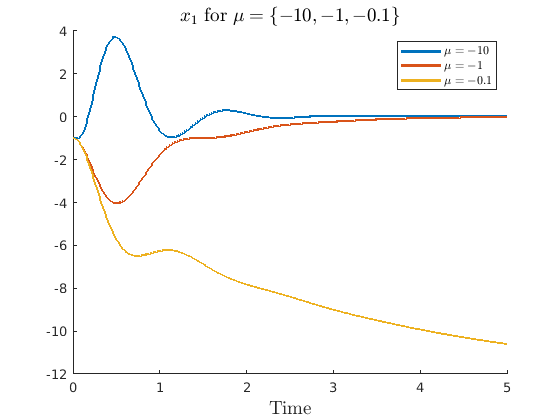

[t, r_01] = ode45(@(t, r) r_func(t, r, -K*r(1:2)), time, [-1; 0; 0; 1;]);
[t, r_e01] = ode45(@(t, r) r_func(t, r, -K*r(3:4)), time, [-1; 0; 0; 1;]);


figure
title("$x_1$ for $\mu=\{-10,-1,-0.1\}$", 'Interpreter', 'latex', "FontSize", 14);
xlabel("Time", 'Interpreter', 'latex', "FontSize", 14);
hold on

plot(time, r_e10(:,1), 'LineWidth', 2)
plot(time, r_e1(:,1), 'LineWidth', 2)
plot(time, r_e01(:,1), 'LineWidth', 2)

legend(["$\mu = -10$", "$\mu = -1$", "$\mu = -0.1$"], 'Interpreter', "latex")

hold off
exportgraphics(gcf,'figures/c3-3-x1-plot.png','Resolution',300)

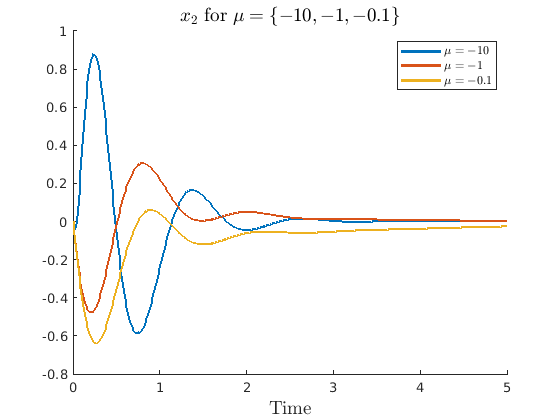


figure
title("$x_2$ for $\mu=\{-10,-1,-0.1\}$", 'Interpreter', 'latex', "FontSize", 14);
xlabel("Time", 'Interpreter', 'latex', "FontSize", 14);
hold on

plot(time, r_e10(:,2), 'LineWidth', 2)
plot(time, r_e1(:,2), 'LineWidth', 2)
plot(time, r_e01(:,2), 'LineWidth', 2)

legend(["$\mu = -10$", "$\mu = -1$", "$\mu = -0.1$"], 'Interpreter', "latex")

hold off
exportgraphics(gcf,'figures/c3-3-x2-plot.png','Resolution',300)


time = 0:0.1:90

time =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


r_func = @(t,r, u) [A zeros(2); K_e_01*C A-(K_e_01*C)]*r+[B; B]*u

r_func = function_handle with value:
    @(t,r,u)[A,zeros(2);K_e_01*C,A-(K_e_01*C)]*r+[B;B]*u


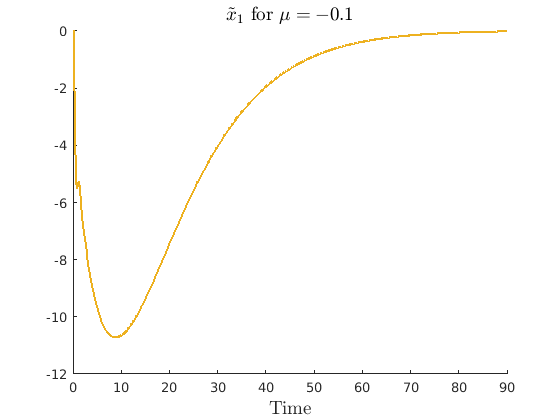

[t, r_e01] = ode45(@(t, r) r_func(t, r, -K*r(3:4)), time, [-1; 0; 0; 1;]);
figure
title("$\tilde{x}_1$ for $\mu = -0.1$", "Interpreter", "latex", "FontSize", 14)
xlabel("Time", "Interpreter", "latex", "FontSize", 14);
hold on

plot(time, r_e01(:,3), 'LineWidth', 2, 'Color', [0.9290 0.6940 0.1250])

hold off
exportgraphics(gcf, "figures/c3-3-01-time-plot.png", "Resolution", 300)

A

A =      0    20
     1     0


transpose(A)

ans =      0     1
    20     0


eig(A)

ans =     4.4721
   -4.4721


eig(transpose(A))

ans =     4.4721
   -4.4721


eig(A-K_e*C)

ans =   -10.0000
  -10.0000


eig(A-K_e_1*C)

ans =    -1.0000
   -1.0000


eig(A-K_e_01*C)

ans =   -0.1000 + 0.0000i
  -0.1000 - 0.0000i
